%% ================================================================
%  ANÁLISE E TRANSFORMAÇÃO DE DADOS – PROJETO 2026
%  Meta 1 – Pontos 1 ao 13 Completos (APENAS PARTICIPANTE 50)
%  Versão Definitiva: Todos os pontos + Correções da Imagem
% ================================================================

clear; clc; close all;

DATA_PATH = fullfile('data');
PARTICIPANTE_ALVO = 50; % <-- DEFINIDO O PARTICIPANTE 50 AQUI

%% ================================================================
%  PONTO 1 – Criação da Estrutura de Dados
% ================================================================
fprintf('=== PONTO 1: Criação da estrutura de dados ===\n');

=== PONTO 1: Criação da estrutura de dados ===



if ~isfolder(DATA_PATH)
    error('Pasta "%s" não encontrada. Ajuste a variável DATA_PATH.', DATA_PATH);
end

participant_dirs = dir(DATA_PATH);
participant_dirs = participant_dirs([participant_dirs.isdir]);
participant_dirs = participant_dirs(~ismember({participant_dirs.name},{'.','..'}));

directory    = {};
filename_col = {};
participant  = [];
digit_col    = [];
repetition   = [];

for p = 1:numel(participant_dirs)
    part_name = participant_dirs(p).name;
    
    if str2double(part_name) ~= PARTICIPANTE_ALVO
        continue; 
    end
    
    part_path = fullfile(DATA_PATH, part_name);
    wav_files = dir(fullfile(part_path, '*.wav'));

    for f = 1:numel(wav_files)
        fname = wav_files(f).name;
        parts = strsplit(fname(1:end-4), '_');

        if numel(parts) < 3
            continue;
        end

        directory{end+1,1}   = part_path;
        filename_col{end+1,1}= fname;
        digit_col(end+1,1)   = str2double(parts{1});
        participant(end+1,1) = str2double(parts{2});
        repetition(end+1,1)  = str2double(parts{3});
    end
end

T = table(directory, filename_col, participant, digit_col, repetition, ...
    'VariableNames',{'Directory','Filename','Participant','Digit','Repetition'});
T = sortrows(T, {'Participant','Digit','Repetition'});

fprintf('Total de ficheiros  : %d\n',   height(T));

Total de ficheiros  : 500


fprintf('Participantes       : %d\n',   numel(unique(T.Participant)));

Participantes       : 1


fprintf('Dígitos             : %s\n',   num2str(unique(T.Digit)'));

Dígitos             : 0  1  2  3  4  5  6  7  8  9


fprintf('Repetições por díg. : %d\n\n', numel(unique(T.Repetition)));

Repetições por díg. : 50




%% ================================================================
%  PONTO 2 – Importação dos Sinais de Áudio
% ================================================================
fprintf('=== PONTO 2: Importação dos sinais de áudio ===\n');

=== PONTO 2: Importação dos sinais de áudio ===



N_files      = height(T);
signals      = cell(N_files, 1);
sample_rates = zeros(N_files, 1);

for i = 1:N_files
    filepath  = fullfile(T.Directory{i}, T.Filename{i});
    [sig, fs] = audioread(filepath);
    if size(sig, 2) > 1, sig = sig(:, 1); end
    signals{i}      = double(sig);
    sample_rates(i) = fs;
end

T.SampleRate = sample_rates;
T.Signal     = signals;
fprintf('Taxa de amostragem : %d Hz\n\n', T.SampleRate(1));

Taxa de amostragem : 48000 Hz




%% ================================================================
%  PONTO 3 – Representação Gráfica dos Sinais Originais
% ================================================================
fprintf('=== PONTO 3: Gráficos dos sinais originais ===\n');

=== PONTO 3: Gráficos dos sinais originais ===


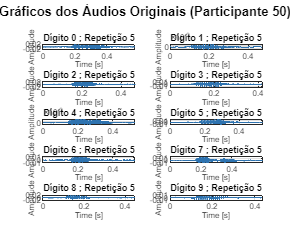


REP_EXAMPLE  = 5;
PART_EXAMPLE = PARTICIPANTE_ALVO; 

mask   = (T.Repetition == REP_EXAMPLE) & (T.Participant == PART_EXAMPLE);
subset = sortrows(T(mask,:), 'Digit');

figure('Name','Gráficos dos Áudios Originais', 'NumberTitle','off', 'Position',[50 50 1100 900]);
sgtitle(sprintf('Gráficos dos Áudios Originais (Participante %d)', PART_EXAMPLE), 'FontSize',13, 'FontWeight','bold');

for i = 1:height(subset)
    sig = subset.Signal{i};
    fs  = subset.SampleRate(i);
    t   = (0:numel(sig)-1) / fs;

    subplot(5, 2, i);
    plot(t, sig, 'Color',[0.18 0.45 0.69], 'LineWidth',0.5);
    title(sprintf('Dígito %d ; Repetição %d', subset.Digit(i), REP_EXAMPLE), 'FontSize',9, 'FontWeight','bold');
    xlabel('Time [s]', 'FontSize',8); ylabel('Amplitude', 'FontSize',8);
    xlim([0, t(end)]); grid on;
end


%% ================================================================
%  PONTO 4 – Pré-processamento dos Sinais
% ================================================================
fprintf('=== PONTO 4: Pré-processamento ===\n');

=== PONTO 4: Pré-processamento ===



WINDOW_MS     = 10;      
ENERGY_THRESH = 0.08;   

trimmed_lens = zeros(N_files, 1);
for i = 1:N_files
    s = remove_silence(T.Signal{i}, T.SampleRate(i), WINDOW_MS, ENERGY_THRESH);
    trimmed_lens(i) = numel(s);
end
target_s   = prctile(trimmed_lens ./ T.SampleRate, 95);
target_len = round(target_s * T.SampleRate(1));

preprocessed = cell(N_files, 1);
for i = 1:N_files
    sig = remove_silence(T.Signal{i}, T.SampleRate(i), WINDOW_MS, ENERGY_THRESH);
    sig = norm_amplitude(sig);
    sig = pad_trim(sig, target_len);
    preprocessed{i} = sig;
end

T.SignalPreprocessed = preprocessed;
fprintf('  Concluído! Todos os sinais com %d amostras.\n\n', target_len);

  Concluído! Todos os sinais com 25146 amostras.




%% ================================================================
%  PONTO 5 – Gráficos dos Sinais Pré-processados
% ================================================================
fprintf('=== PONTO 5: Gráficos dos sinais pré-processados ===\n');

=== PONTO 5: Gráficos dos sinais pré-processados ===


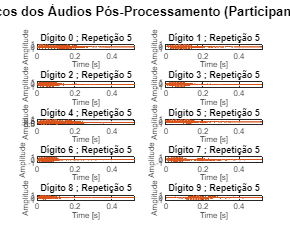


mask_pre   = (T.Repetition == REP_EXAMPLE) & (T.Participant == PART_EXAMPLE);
subset_pre = sortrows(T(mask_pre,:), 'Digit');

figure('Name','Gráficos dos Áudios Pós-Processamento', 'NumberTitle','off', 'Position',[100 100 1100 900]);
sgtitle(sprintf('Gráficos dos Áudios Pós-Processamento (Participante %d)', PART_EXAMPLE), 'FontSize',13, 'FontWeight','bold');

for i = 1:height(subset_pre)
    sig = subset_pre.SignalPreprocessed{i};
    fs  = subset_pre.SampleRate(i);
    t   = (0:numel(sig)-1) / fs;

    subplot(5, 2, i);
    plot(t, sig, 'Color',[0.85 0.33 0.10], 'LineWidth',0.5);
    title(sprintf('Dígito %d ; Repetição %d', subset_pre.Digit(i), REP_EXAMPLE), 'FontSize',9, 'FontWeight','bold');
    xlabel('Time [s]', 'FontSize',8); ylabel('Amplitude', 'FontSize',8);
    xlim([0, t(end)]); grid on;
end


%% ================================================================
%  PONTO 6 – Comparação Visual: Original vs Pré-processado
% ================================================================
fprintf('=== PONTO 6: Comparação Original vs Pré-processado ===\n');

=== PONTO 6: Comparação Original vs Pré-processado ===


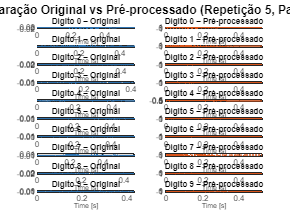


digits_list = sort(unique(T.Digit))';

figure('Name','Comparação Original vs Pré-processado', 'NumberTitle','off', 'Position',[150 150 1300 1000]);
sgtitle(sprintf('Comparação Original vs Pré-processado (Repetição %d, Part. %d)', REP_EXAMPLE, PART_EXAMPLE), 'FontSize',12, 'FontWeight','bold');

for i = 1:numel(digits_list)
    d   = digits_list(i);
    idx = find(T.Digit==d & T.Repetition==REP_EXAMPLE & T.Participant==PART_EXAMPLE, 1);

    fs    = T.SampleRate(idx);
    s_ori = T.Signal{idx};
    s_pre = T.SignalPreprocessed{idx};
    t_ori = (0:numel(s_ori)-1) / fs;
    t_pre = (0:numel(s_pre)-1) / fs;

    subplot(10, 2, 2*i-1);
    plot(t_ori, s_ori, 'Color',[0.18 0.45 0.69], 'LineWidth',0.5);
    title(sprintf('Dígito %d – Original', d), 'FontSize',8, 'FontWeight','bold');
    xlabel('Time [s]','FontSize',7); ylabel('Amplitude','FontSize',7);
    xlim([0, t_ori(end)]); grid on;

    subplot(10, 2, 2*i);
    plot(t_pre, s_pre, 'Color',[0.85 0.33 0.10], 'LineWidth',0.5);
    title(sprintf('Dígito %d – Pré-processado', d), 'FontSize',8, 'FontWeight','bold');
    xlabel('Time [s]','FontSize',7); ylabel('Amplitude','FontSize',7);
    xlim([0, t_pre(end)]); grid on;
end


%% ================================================================
%  PONTO 7 – Características Temporais (Com Janelas de Tempo - CORRIGIDO)
% ================================================================
fprintf('=== PONTO 7: Cálculo de features temporais em Janelas ===\n');

=== PONTO 7: Cálculo de features temporais em Janelas ===



feat_energy_total = zeros(N_files, 1);
feat_amp_max      = zeros(N_files, 1);
feat_amp_std      = zeros(N_files, 1);
feat_freq_mean    = zeros(N_files, 1); 
feat_freq_std     = zeros(N_files, 1); 
feat_energy_onset = zeros(N_files, 1);
feat_rms          = zeros(N_files, 1);

for i = 1:N_files
    sig  = T.SignalPreprocessed{i};
    fs_sig = T.SampleRate(i);
    n    = numel(sig);
    q1   = floor(n / 4);

    feat_energy_total(i)  = sum(sig .^ 2);
    feat_amp_max(i)       = max(abs(sig));
    feat_amp_std(i)       = std(sig);
    feat_energy_onset(i)  = sum(sig(1:q1) .^ 2);
    feat_rms(i)           = sqrt(mean(sig .^ 2));
    
    % --- CORREÇÃO: Frequência em Janelas de Tempo ---
    win_samples = round(0.02 * fs_sig); % Janela de 20ms
    n_frames = floor(n / win_samples);
    freq_windows = zeros(n_frames, 1);
    
    for w = 1:n_frames
        frame = sig((w-1)*win_samples+1 : w*win_samples);
        zcr_frame = sum(abs(diff(sign(frame)))) / (2 * win_samples);
        freq_windows(w) = zcr_frame * fs_sig / 2; 
    end
    
    feat_freq_mean(i) = mean(freq_windows);
    feat_freq_std(i)  = std(freq_windows);
end

T.FeatEnergyTotal = feat_energy_total;
T.FeatAmpMax      = feat_amp_max;
T.FeatAmpStd      = feat_amp_std;
T.FeatFreqMean    = feat_freq_mean; 
T.FeatFreqStd     = feat_freq_std;  
T.FeatEnergyOnset = feat_energy_onset;
T.FeatRMS         = feat_rms;
fprintf('  Colunas adicionadas à tabela.\n\n');

  Colunas adicionadas à tabela.




%% ================================================================
%  PONTO 8 – Seleção Gráfica das Características Temporais
% ================================================================
fprintf('=== PONTO 8: Seleção de Features Temporais ===\n');

=== PONTO 8: Seleção de Features Temporais ===


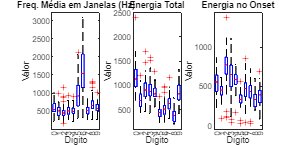


figure('Name','Boxplots - Features Temporais', 'Position',[100 100 1200 600]);
subplot(1,3,1); boxplot(T.FeatFreqMean, T.Digit); title('Freq. Média em Janelas (Hz)'); xlabel('Dígito'); ylabel('Valor');
subplot(1,3,2); boxplot(T.FeatEnergyTotal, T.Digit); title('Energia Total'); xlabel('Dígito'); ylabel('Valor');
subplot(1,3,3); boxplot(T.FeatEnergyOnset, T.Digit); title('Energia no Onset'); xlabel('Dígito'); ylabel('Valor');


fprintf('  1. Freq. Média em Janelas - reflete o conteúdo médio de frequência ao longo do tempo.\n');

  1. Freq. Média em Janelas - reflete o conteúdo médio de frequência ao longo do tempo.


fprintf('  2. Energia Total - útil pois a duração/intensidade vocálica varia entre os dígitos.\n');

  2. Energia Total - útil pois a duração/intensidade vocálica varia entre os dígitos.


fprintf('  3. Energia no Onset - capta os ataques percussivos ou plosivos das consoantes.\n\n');

  3. Energia no Onset - capta os ataques percussivos ou plosivos das consoantes.




%% ================================================================
%  PONTO 8B – Scatter Plot 3D das Características Temporais
% ================================================================
fprintf('\n=== PONTO 8B: Scatter Plot 3D (Features Temporais) ===\n');


=== PONTO 8B: Scatter Plot 3D (Features Temporais) ===


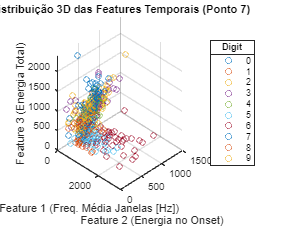


figure('Name','3D Scatter Plot Features Temporais', 'Position',[150 150 900 700]);
hold on; grid on;

% Criar paleta de cores para os 10 dígitos
cores_temporais = lines(10); 

% Plotar cada dígito separadamente para criar a legenda e atribuir a cor certa
for d = 0:9
    idx = (T.Digit == d);
    
    % Eixos baseados nas features extraídas no Ponto 7
    X_data_temp = T.FeatFreqMean(idx);      % A frequência das janelas de tempo
    Y_data_temp = T.FeatEnergyOnset(idx);   % A energia inicial do sinal
    Z_data_temp = T.FeatEnergyTotal(idx);   % A energia total do sinal
    
    % Desenhar os pontos como círculos vazados ('o')
    scatter3(X_data_temp, Y_data_temp, Z_data_temp, 30, cores_temporais(d+1,:), 'o');
end

% Ajuste da perspetiva e formatação
view(45, 30);
xlabel('Feature 1 (Freq. Média Janelas [Hz])');
ylabel('Feature 2 (Energia no Onset)');
zlabel('Feature 3 (Energia Total)');
title('Distribuição 3D das Features Temporais (Ponto 7)');

% Caixa de legenda à direita com os dígitos de 0 a 9
lgd_temp = legend(string(0:9), 'Location', 'eastoutside');
title(lgd_temp, 'Digit');
hold off;


%% ================================================================
%  PONTO 9 – Série Complexa de Fourier
% ================================================================
fprintf('=== PONTO 9: Coeficientes da Série Complexa de Fourier ===\n');

=== PONTO 9: Coeficientes da Série Complexa de Fourier ===



fft_coeffs = cell(N_files, 1);
for i = 1:N_files
    % CORREÇÃO: Dividir por N para obter os coeficientes reais da série de Fourier
    fft_coeffs{i} = fft(T.SignalPreprocessed{i}) / target_len;
end
T.FFT_Coeffs = fft_coeffs;
fprintf('  Coeficientes guardados na tabela.\n\n');

  Coeficientes guardados na tabela.




%% ================================================================
%  PONTO 10 – Espectro de Amplitude Mediano e Quartis 
% ================================================================
fprintf('=== PONTO 10: Espectro de Amplitude Mediano e Quartis ===\n');

=== PONTO 10: Espectro de Amplitude Mediano e Quartis ===


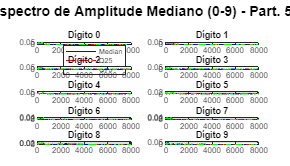


N = target_len;
pos_freqs = 1:floor(N/2);
fs = T.SampleRate(1);
freq_axis = (0:floor(N/2)-1) * (fs / N);

figure('Name','Espectro de Amplitude', 'Position',[50 50 1400 800]);
sgtitle(sprintf('Espectro de Amplitude Mediano (0-9) - Part. %d', PARTICIPANTE_ALVO), 'FontSize', 14, 'FontWeight', 'bold');

for d = 0:9
    idx_d = find(T.Digit == d);
    num_d = length(idx_d);
    
    amp_matrix = zeros(num_d, length(pos_freqs));
    
    for k = 1:num_d
       
        amp_full = abs(T.FFT_Coeffs{idx_d(k)}); 
        amp_full(2:end) = 2 * amp_full(2:end); 
        amp_matrix(k, :) = amp_full(pos_freqs);
    end
    
    med_spec = quantile(amp_matrix, 0.50, 1);
    q25_spec = quantile(amp_matrix, 0.25, 1);
    q75_spec = quantile(amp_matrix, 0.75, 1);
    
    subplot(5, 2, d+1);
    plot(freq_axis, med_spec, 'b', 'LineWidth', 1); hold on;
    plot(freq_axis, q25_spec, 'r--', 'LineWidth', 0.5);
    plot(freq_axis, q75_spec, 'g--', 'LineWidth', 0.5);
    title(sprintf('Dígito %d', d));
    xlim([0, 8000]); 
    if d == 0, legend('Median', 'Q25', 'Q75'); end
    grid on;
end


%% ================================================================
%  PONTO 11 – Características Espectrais (Atualizado)
% ================================================================
fprintf('\n=== PONTO 11: Cálculo de Features Espectrais ===\n');


=== PONTO 11: Cálculo de Features Espectrais ===



feat_spec_centroid = zeros(N_files, 1);
feat_spec_max_amp  = zeros(N_files, 1);
feat_spec_max_freq = zeros(N_files, 1);
feat_spec_mean     = zeros(N_files, 1);
feat_spec_rolloff  = zeros(N_files, 1);

for i = 1:N_files
    % CORREÇÃO: Aplicar fator unilateral (*2)
    amp = abs(T.FFT_Coeffs{i}(pos_freqs));
    amp(2:end) = 2 * amp(2:end);
    
    feat_spec_centroid(i) = sum(freq_axis' .* amp) / (sum(amp) + eps);
    [m_amp, m_idx] = max(amp);
    feat_spec_max_amp(i) = m_amp;
    feat_spec_max_freq(i) = freq_axis(m_idx);
    feat_spec_mean(i) = mean(amp);
    
    cum_energy = cumsum(amp.^2);
    total_energy = cum_energy(end);
    idx_rolloff = find(cum_energy >= 0.85 * total_energy, 1);
    if isempty(idx_rolloff), idx_rolloff = length(freq_axis); end
    feat_spec_rolloff(i) = freq_axis(idx_rolloff);
end

T.FeatSpecCentroid = feat_spec_centroid;
T.FeatSpecMaxAmp   = feat_spec_max_amp;
T.FeatSpecMaxFreq  = feat_spec_max_freq;
T.FeatSpecMean     = feat_spec_mean;
T.FeatSpecRolloff  = feat_spec_rolloff;

%% ================================================================
%  PONTO 12 – Seleção Gráfica das Características Espectrais
% ================================================================
fprintf('\n=== PONTO 12: Seleção de Features Espectrais ===\n');


=== PONTO 12: Seleção de Features Espectrais ===


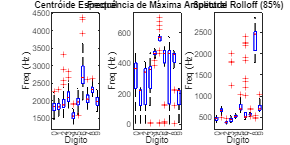


figure('Name','Boxplots - Features Espectrais', 'Position',[150 150 1200 600]);
subplot(1,3,1); boxplot(T.FeatSpecCentroid, T.Digit); title('Centróide Espectral'); xlabel('Dígito'); ylabel('Freq (Hz)');
subplot(1,3,2); boxplot(T.FeatSpecMaxFreq, T.Digit); title('Frequência de Máxima Amplitude'); xlabel('Dígito'); ylabel('Freq (Hz)');
subplot(1,3,3); boxplot(T.FeatSpecRolloff, T.Digit); title('Spectral Rolloff (85%)'); xlabel('Dígito'); ylabel('Freq (Hz)');


%% ================================================================
%  NOVO PONTO 12B – Scatter Plot 3D (CUMPRINDO O CHECKBOX DA IMAGEM)
% ================================================================
fprintf('\n=== PONTO 12B: Scatter Plot 3D (Requisito da Imagem) ===\n');


=== PONTO 12B: Scatter Plot 3D (Requisito da Imagem) ===


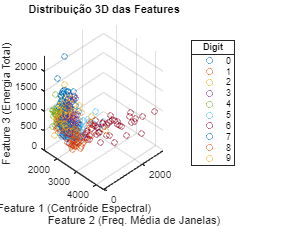


figure('Name','3D Scatter Plot Features', 'Position',[200 200 900 700]);
hold on; grid on;

% Criar paleta de cores para os 10 dígitos
cores = lines(10); 

% Plotar cada dígito separadamente para criar a legenda
for d = 0:9
    idx = (T.Digit == d);
    
    % Eixos baseados nas features extraídas
    X_data = T.FeatSpecCentroid(idx);
    Y_data = T.FeatFreqMean(idx);
    Z_data = T.FeatEnergyTotal(idx);
    
    % Usa 'o' (círculos vazados) como na imagem de referência
    scatter3(X_data, Y_data, Z_data, 30, cores(d+1,:), 'o');
end

view(45, 30);
xlabel('Feature 1 (Centróide Espectral)');
ylabel('Feature 2 (Freq. Média de Janelas)');
zlabel('Feature 3 (Energia Total)');
title('Distribuição 3D das Features');

% Caixa de legenda à direita de 0 a 9
lgd = legend(string(0:9), 'Location', 'eastoutside');
title(lgd, 'Digit');
hold off;


%% ================================================================
%  PONTO 13 – Limpeza e Gravação dos Dados
% ================================================================
fprintf('\n=== PONTO 13: Limpeza e Gravação (Meta 1) ===\n');


=== PONTO 13: Limpeza e Gravação (Meta 1) ===


T.Signal = [];
save('dados_projeto_meta1_part50.mat', 'T', '-v7.3');
fprintf('  FIM DA META 1.\n\n');

  FIM DA META 1.




%% ================================================================
%  FUNÇÕES LOCAIS
% ================================================================

function sig_out = remove_silence(sig, fs, window_ms, thresh)
    win_samples = round(fs * window_ms / 1000);
    n_frames    = floor(numel(sig) / win_samples);
    if n_frames == 0, sig_out = sig; return; end

    energies = zeros(n_frames, 1);
    for k = 1:n_frames
        frame       = sig((k-1)*win_samples+1 : k*win_samples);
        energies(k) = sum(frame .^ 2);
    end

    max_e = max(energies);
    if max_e == 0, sig_out = sig; return; end

    onset = find(energies / max_e > thresh, 1, 'first');
    if isempty(onset), sig_out = sig; return; end

    sig_out = sig((onset-1)*win_samples+1 : end);
end

function sig_out = norm_amplitude(sig)
    mv = max(abs(sig));
    if mv == 0, sig_out = sig; return; end
    sig_out = sig / mv;
end

function sig_out = pad_trim(sig, target_len)
    if numel(sig) >= target_len
        sig_out = sig(1:target_len);
    else
        sig_out = [sig; zeros(target_len - numel(sig), 1)];
    end
end